%% Script for the derivation of light correction function parameters
img = imread('DATA/test/IMG_0106.jpg');  %Read the reference image, with no particles loaded (or covered)
info = imfinfo('DATA/test/IMG_0106.jpg');  %Save the image information
Width = double(info.Width);
Height = double(info.Height);
img = im2double(img);  %Store the image with intensities scaled [0 1]

% Consider a horizontal test line from the image edge to centre
test_line = img(0.5*Height-100, 1:0.5*Width);  %Intensity values along the test line
dist = linspace(length(test_line),1,length(test_line));  %Distance from centre along the test line
% Fit a quadratic curve to relating distance and intensity
coefficients = polyfit(dist, test_line, 2);
xFit = linspace(min(dist), max(dist), 3000);
yFit = polyval(coefficients, xFit);
% Transform the obtained function to find the intensity correction function coefficients
coefficients_corr = [-coefficients(1) coefficients(2) 0];
% Fit the distances into the function and add to the existing intensities
I_corr_1 = polyval(coefficients_corr, dist);
I_corr_2 = test_line + I_corr_1;


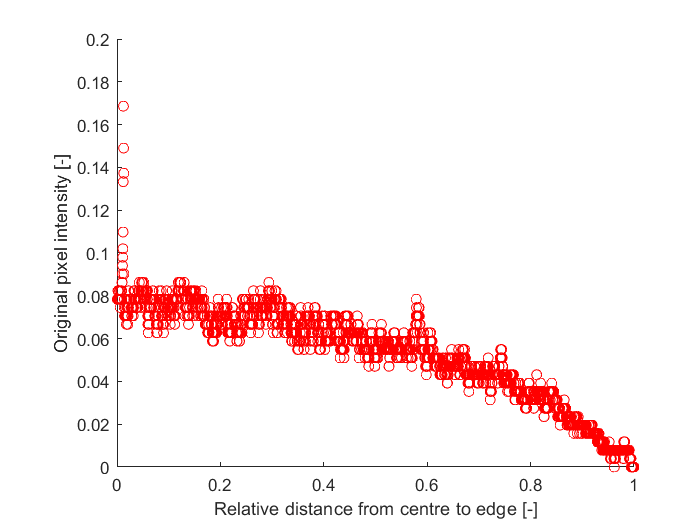

% Plot to check, use relative distances
rel_dist = dist/max(dist);
scatter(rel_dist, test_line, 'ro')
xlabel('Relative distance from centre to edge [-]')
ylabel({'', '', 'Original pixel intensity [-]'})
ylim([0 0.20])

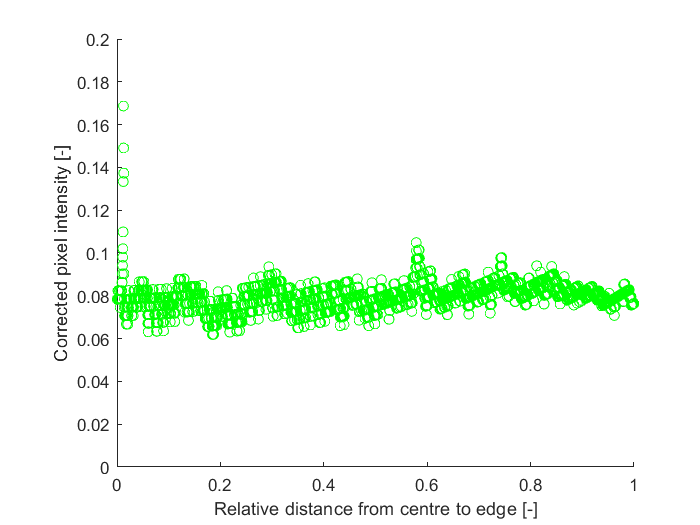


scatter(rel_dist, I_corr_2, 'go')
xlabel('Relative distance from centre to edge [-]')
ylabel({'', '', 'Corrected pixel intensity [-]'})
ylim([0 0.20])